# Nearest Neighbor Classification

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the pump features and partitions it into training and testing

T = readtable("./data/pumpFeatures.csv");
rng(0)
cv = cvpartition(size(T, 1), "HoldOut", 0.3);
dataTrain = T(cv.training, :);
dataTest = T(cv.test, :)

dataTest = 300×85 table
    wMotor_mean    wMotor_std    wMotor_fftPeakIdx    wMotor_skewness    wMotor_kurtosis    wMotor_peak2peak    wMotor_peak2rms    wMotor_rms    wMotor_mad    wMotor_csRange    wMotor_pLow    wMotor_pMid    wMotor_pHigh    wMotor_pKur    iMotor_mean    iMotor_std    iMotor_fftPeakIdx    iMotor_skewness    iMotor_kurtosis    iMotor_peak2peak    iMotor_peak2rms    iMotor_rms    iMotor_mad    iMotor_csRange    iMotor_pLow    iMotor_pMid    iMotor_pHigh    iMotor_pKur    qIn_mean   

## Task 1

To construct a k-nearest neighbor classifier in MATLAB, use the `fitcknn` function with the data table as input and specify the name of the response variable. By default, a single neighbor is used for the classification (k = 1). To specify k in the model, use the `"NumNeighbors"` property:

`knnModel` `=` `fitcknn``(``tableData``,``...`

    `"ResponseVariable"``,``...`

    `"NumNeighbors"``,``4``)``;`

mdlkNN = fitcknn(dataTrain, "faultCode", "NumNeighbors", 3);

Evaluate model

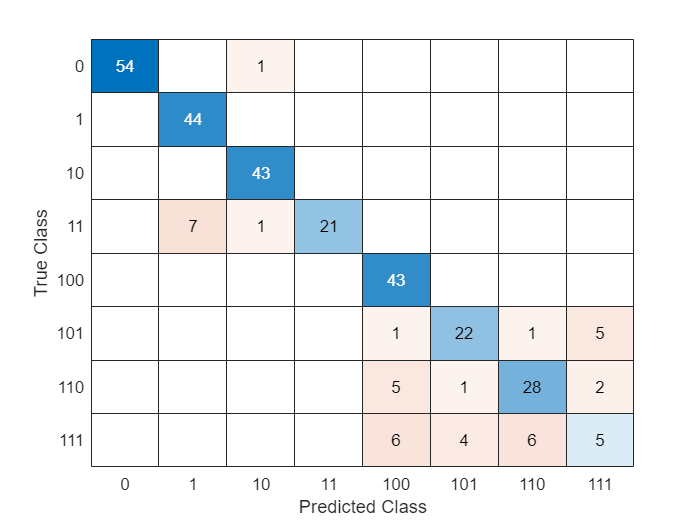

Training Error: 0.07
Loss: 0.16902


evalModel(dataTest, mdlkNN)

## Task 2

Using more neighbors for the predictions may reduce the risk of overfitting.

Instead of modifying the `fitcknn` function call, you can change the number of neighbors *after* the model has been created.

To change *k* after model creation, use dot notation with the `NumNeighbors` property.

`model``.``PropertyName` `=` `newPropertyValue`

mdlkNN.NumNeighbors = 7;

Evaluate model

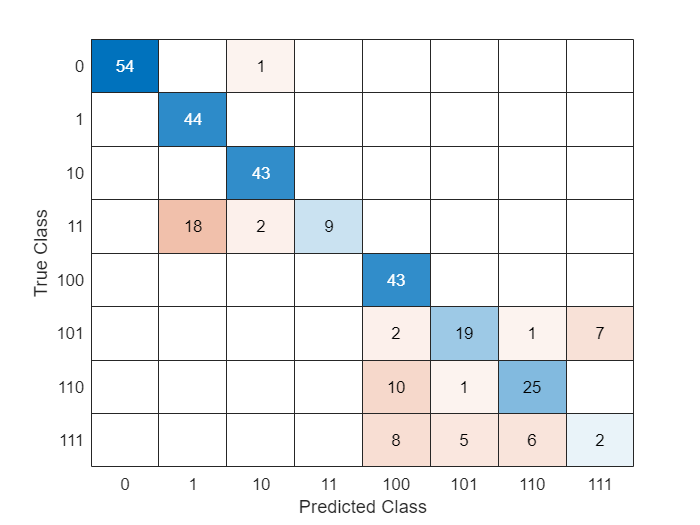

Training Error: 0.16714
Loss: 0.25029


evalModel(dataTest, mdlkNN)

## Task 3

You may want to train this algorithm using different parameters to best fit your data. Some common parameters to modify are `"Distance"` and `"DistanceWeight"`.

`knnModel` `=` `fitcknn``(``tableData``,``"``ResponseVariable``"``,``...`

                  `"NumNeighbors"``,``4``,``...`

                  `"Distance"``,``"cosine"``,``...`

                  `"DistanceWeight"``,``"inverse"``)``;`

mdlkNN = fitcknn(dataTrain, "faultCode", ...
                "NumNeighbors", 7,...
                "Distance", "correlation", ...
                "DistanceWeight", "squaredinverse");

Evaluate model

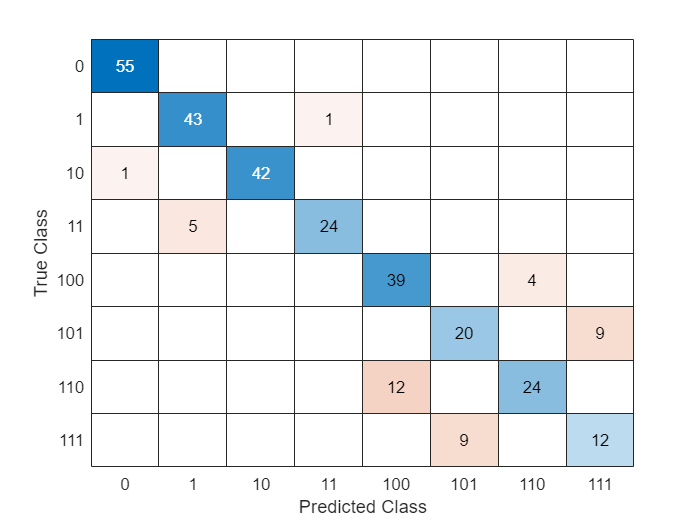

Training Error: 0
Loss: 0.15457


evalModel(dataTest, mdlkNN)

Do not edit. This function is used to evaluate a model by displaying the confusion chart, training error, and test loss.

function evalModel(dataTest, mdl)
    confusionchart(dataTest.faultCode, predict(mdl, dataTest))
    disp("Training Error: " + resubLoss(mdl))
    disp("Loss: " + loss(mdl, dataTest))
end